# `Experiment-1`

### **1) Newton-Raphson method:**

Q. Find a real root of $x^2 +3x+2=0$ near $x_0 =-0\ldotp 5$ using Newton-Raphson method.

x0=-0.5

x0 = -0.5000

f=@(x) x.^2+3*x+2;
df=@(x) 2*x+3;
NRM(x0,f,df)

The aproximated root after 5 iteration is -1.000000


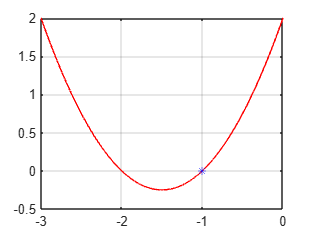

grid on

function[]=NRM(x0,f,df)
x(1)=x0;
Tol=10^(-5);
maxit=50;
for i=1:maxit
    if abs(df(x(i)))<10^(-10)
        fprintf("The derivative zero at x=%f\n",x(i))
        break
    end
x(i+1)=x(i)-f(x(i))/df(x(i));
if abs(x(i+1)-x(i))<Tol
    fprintf("The aproximated root after %d iteration is %f\n",i,x(i+1))
    break
end
end
%Graph of f and root
t=-3:0.001:0;
y=f(t);
plot(t,y,'r',x(i+1),0,'b*')
end

### 2) Simpson's 1/3rd rule of Integration:

function[I]=simpson13(y,a,b,n)
if mod(n,2)==1
    disp("n must be even");
    return
end
h=(b-a)/n;
if numel(y)>1
    I=(h/3)*(y(1)+y(n+1)+4*sum(y(2:2:n))+2*sum(y(3:2:n-1)));
else
    x=a:h:b;
    I=(h/3)*(y(a)+y(b)+4*sum(y(x(2:2:n)))+2*sum(y(x(3:2:n-1))));
end
end

#### `(A) Assignment Questions:`

1) $\int_0^{0\ldotp 6} e^{{-x}^2 }$ by taking 6 equal sub-intervals.

y=@(x)exp(-x.^2);
a=0;
b=0.6;
n=6;
simpson13(y,a,b,n)

ans = 0.5352

2) $\int_1^3 e^{\frac{1}{x}} \;\textrm{dx}$ by taking 4 equal sub-intervals.

y=@(x) exp(1./x);
a=1;
b=3;
n=4;
simpson13(y,a,b,n)

ans = 3.5283

3) $\int_0^5 \frac{1}{4x+5}\textrm{dx}$ by taking 10 equal sub-intervals.

y=@(x) (1./(4*x+5));
a=0;
b=5;
n=10;
simpson13(y,a,b,n)

ans = 0.4025

4)$\int_2^8 \frac{1}{\log_{10} \left(x\right)}\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) (1./(log10(x)));
a=2;
b=8;
n=6;
simpson13(y,a,b,n)

ans = 9.7203

5)$\int_4^{5\ldotp 2} \log \left(x\right)\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) ((log(x)));
a=4;
b=5.2;
n=6;
simpson13(y,a,b,n)

ans = 1.8278

6) $\int_0^{0\ldotp 3} \sqrt{1-8x^3 }\textrm{dx}$ by taking 7 ordinate points i.e 6 equal sub-intervals.

y=@(x) (sqrt(1-8*x.^3));
a=0;
b=0.3;
n=6;
simpson13(y,a,b,n)

ans = 0.2916

### 3) Simpson's 3/8th rule of Integration:

function[I]=simpson38(y,a,b,n)
if mod(n,3)~=0
disp("n must be multiple of 3");
return
end
h=(b-a)/n;
if numel(y)>1
I=(h*3/8)*(y(1)+y(n+1)+3*(sum(y(2:3:n-1))+sum(y(3:3:n))+2*sum(y(4:3:n-2))));
else
x=a:h:b;
I=(3*h/8)*(y(a)+y(b)+3*(sum(y(x(2:3:n-1)))+sum(y(x(3:3:n))))+2*sum(y(x(4:3:n-2))));
end
end

#### `(B) Assignment Questions:`

Q. $\int_2^8 \frac{1}{\log_{10} \left(x\right)}\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) 1./log10(x);
a=2;
b=8;
n=6;
I1=simpson38(y,a,b,n)

I1 = 9.7374

Q. $\int_0^{0\ldotp 3} \sqrt{1-8x^3 }\textrm{dx}$ by taking 7 ordinate points i.e 6 equal sub-intervals.

y=@(x) sqrt(1-8*x.^3);
a=0;
b=0.3;
n=6;
I2=simpson38(y,a,b,n)

I2 = 0.2916

### 4) Lagrange Interpolation:

function[poly]=lagr_poly(x,y);
n=length(x);
syms t;
poly=0;
for i=1:n
    prod=1;
for j=1:n
    if i~=j
        prod=prod*(t-x(j))/(x(i)-x(j));
    end
end
poly=poly+prod*y(i);
end
poly(t)=simplify(poly);
t=x(1):0.01:x(n);
z=eval(poly);
plot(x,y,'*',t,z,'b')
grid on
end

#### `(C) Assignment Questions:`

Q1)

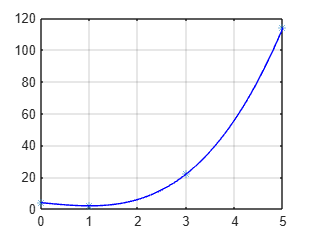

$$Q1(t) = t^{3}-3\,t+4$$

x=[0 1 3 5];
y=[4 2 22 114];
Q1=lagr_poly(x,y)

double(Q1(2.3))

ans = 9.2670

Q2)

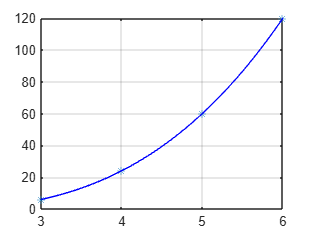

$$Q2(t) = t\,\left(t^{2}-3\,t+2\right)$$

x=[3 4 5 6];
y=[6 24 60 120];
Q2=lagr_poly(x,y)

Q3)

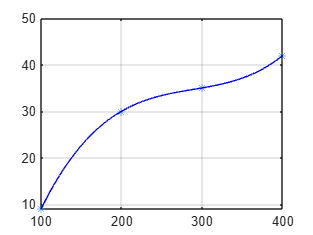

$$Q3(t) = \frac{3\,t^{3}}{1000000}-\frac{13\,t^{2}}{5000}+\frac{39\,t}{50}-46$$

x=[100 200 300 400];
y=[9 30 35 42];
Q3=lagr_poly(x,y)

double(Q3(150))

ans = 22.6250

Q4)

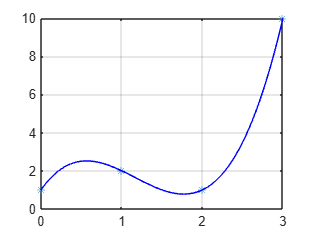

$$Q4(t) = 2\,t^{3}-7\,t^{2}+6\,t+1$$

x=[0 1 2 3];
y=[1 2 1 10];
Q4=lagr_poly(x,y)

double(Q4(0.3))

ans = 2.2240

double(Q4(2.8))

ans = 6.8240

Q5)

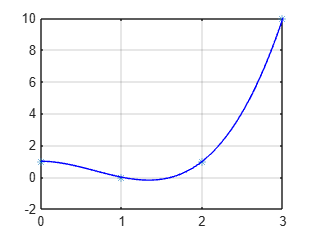

$$Q5(t) = t^{3}-2\,t^{2}+1$$

x=[0 1 2 3];
y=[1 0 1 10];
Q5=lagr_poly(x,y)

double(Q5(4))

ans = 33

Q6)

$$Q6(t) = t^{3}-2\,t^{2}+1$$

x=[0 1 2 3];
y=[1 0 1 10];
Q6=lagr_poly(x,y)

double(Q6(10))

ans = 801

Q7)

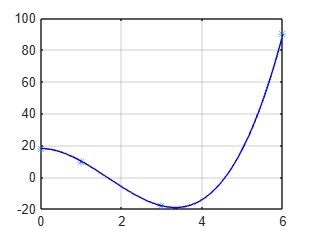

$$Q7(t) = 2\,t^{3}-10\,t^{2}+18$$

x=[0 1 3 6];
y=[18 10 -18 90];
Q7=lagr_poly(x,y)

double(Q7(5))

ans = 18